warning off
clear all
close all
clc
addpath(genpath('..'));

[data_points1, size] = parseSection('3dFab_1.txt');


data_point_obj1 = data_points1(1);
data_point_obj1 = data_point_obj1.Normalize; 
plot(1:length(data_point_obj1.odd),data_point_obj1.odd); 

**Generate Fourier Coefficients**

% Determine Fourier coefficients for each data_point
fs_order = 14;

data_point_obj1 = data_point_obj1.GenerateFourier(fs_order);

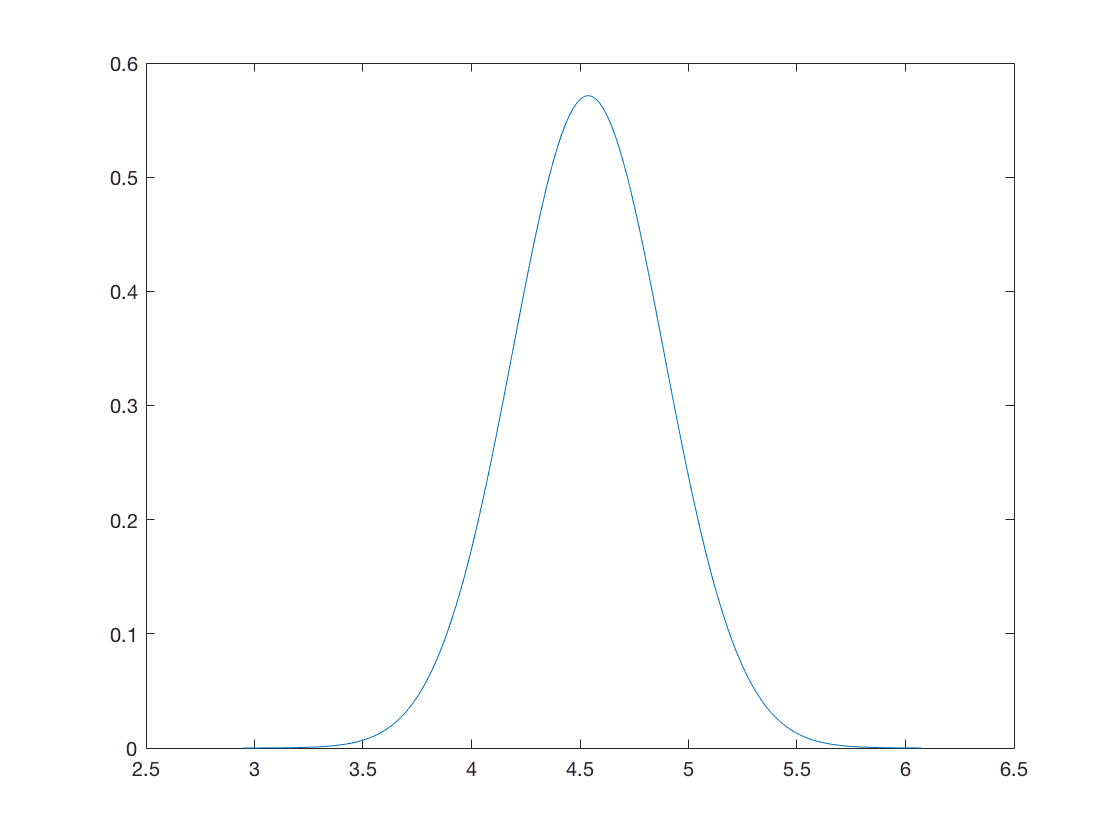

[piSegment, piSegmentRange] = data_point_obj1.GetODDPiSegment();

plot(piSegmentRange, piSegment);


mean = compute_mean(piSegment, piSegmentRange);
[oi, sd] = compute_orientation_index(mean, piSegment, piSegmentRange);
data_point_obj1.mean_odd = mean;
data_point_obj1.oi_odd = oi;
data_point_obj1.sd_odd = sd;

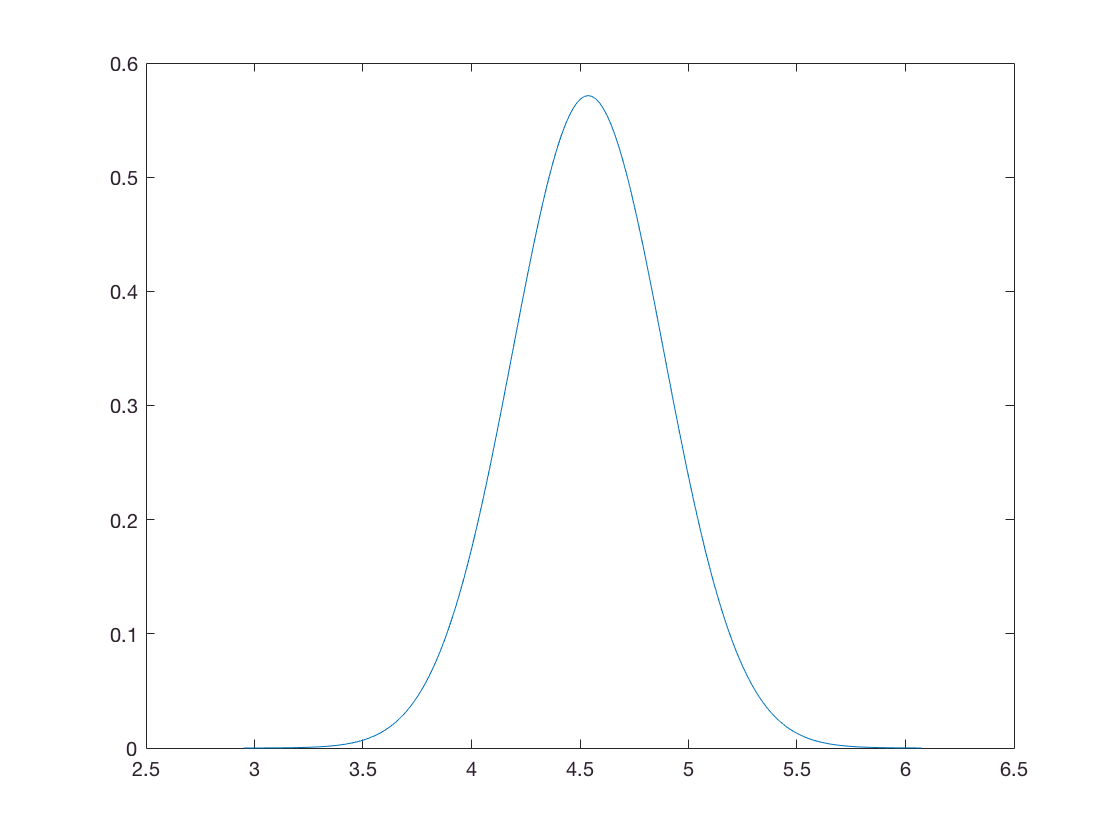

[piSegmentODF, piSegmentRangeODF] = data_point_obj1.GetODFPiSegment();

plot(piSegmentRangeODF, piSegmentODF);


meanODF = compute_mean(piSegmentODF, piSegmentRangeODF);
[oi, sd] = compute_orientation_index(meanODF, piSegmentODF, piSegmentRangeODF);
data_point_obj1.mean_odf = meanODF;
data_point_obj1.oi_odf = oi;
data_point_obj1.sd_odf = sd;